# **Effet d'une arthroplastie totale inversée d'épaule sur les synergies musculaires**

**Analyse synergies sujet par sujet pour un mouvement fonctionnel**

Paramètres

% 1) initializeParameters : regroupe tous les paramètres et configurations 
% tels que les muscles, les labels des tâches, le traitement de données, 
% l'assignation des tâches analytiques et la séparation des données en 3 cycles

Traitement des données

% 1) calculateMVC : calcul la contraction maximale volontaire pour le sujet
% et les muscles selon la tâche analytic assignée à chaque muscle en prenant 
% la moyenne des cinq valeurs les plus hautes du signal RMS analytic 
% (normalisation par une tâche sous-maximale standardisée)

% 2) processEMGSignal : traitement des données pour un muscle 

% 3) all_functional_data : traitement des données fonctionnelles pour un sujet

Calcul et assemblage des cycles 

% 1) detectMovementCycles: détecte les cycles en basant sur le marqueur
% RHLE (épicondyle latéral du coude)

% 2) identifyCycles : identifie les trois cycles pour chaque mouvement

% 3) mergeCycles : fusionne les cycles ensemble

Affichage des cycles 

% 1) plotCycleDetection : visualise la détection des cycles de mouvement

% 2) plotCycleSequence : visualise l'enchaînement des cycles pour tous les muscles

Affichage et sauvegarde de la matrice finale des données EMG traitées

% 1) saveDataMatrix : affiche et sauvegarde la matrice finale 

% Script principal
clc, clear all;

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Toolboxs\btk'));

% Définition des deux groupes de sujets
subjects_asymptomatic = {'A1'}; % 1-41

subjects_pre_operation = {'S1'}; % 1-41

subjects_post_operation = {'S1'}; % 1-41

% Choix du groupe à utiliser
disp('Choisissez le groupe de sujets à analyser:');

Choisissez le groupe de sujets à analyser:


disp('1 - asymptomatic');

1 - asymptomatic


disp('2 - pre_operation');

2 - pre_operation


disp('3 - post_operation');

3 - post_operation


groupe_choix = input('Choix du groupe (1, 2 ou 3): ');

% Sélection du groupe selon le choix
if groupe_choix == 1
    subjects = subjects_asymptomatic;
    disp('Groupe 1 sélectionné.');
elseif groupe_choix == 2
    subjects = subjects_pre_operation;
    disp('Groupe 2 sélectionné.');
elseif groupe_choix == 3
    subjects = subjects_post_operation;
    disp('Groupe 3 sélectionné.');
else
    error('Choix invalide. Veuillez entrer 1, 2 ou 3.');
end

Groupe 1 sélectionné.


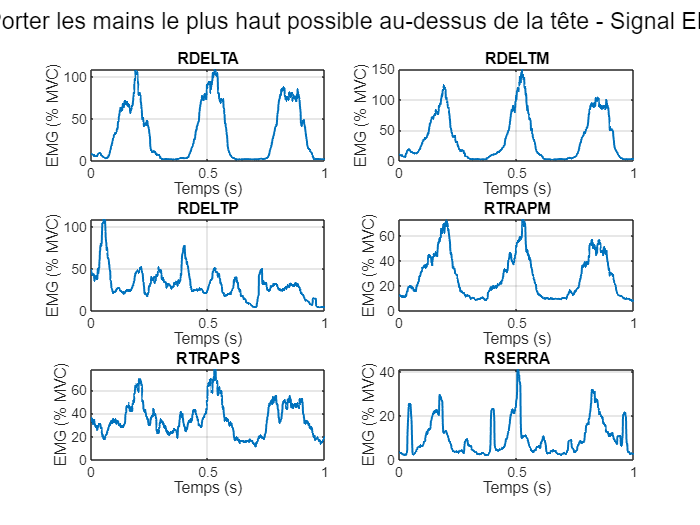

Vérification de l'ordre temporel des cycles :
Cycle 1: Début à 1.84 s, Fin à 4.36 s (Durée: 2.51 s)
Cycle 2: Début à 7.91 s, Fin à 10.13 s (Durée: 2.22 s)
Cycle 3: Début à 13.73 s, Fin à 16.03 s (Durée: 2.30 s)
Confirmation: Les cycles sont dans l'ordre temporel croissant.


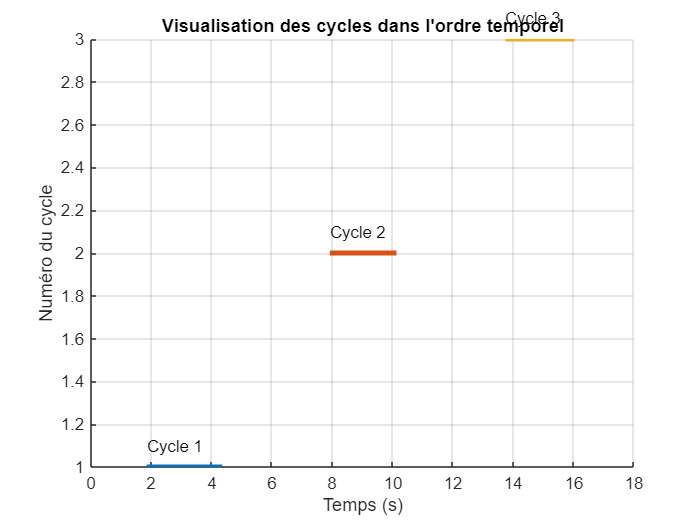

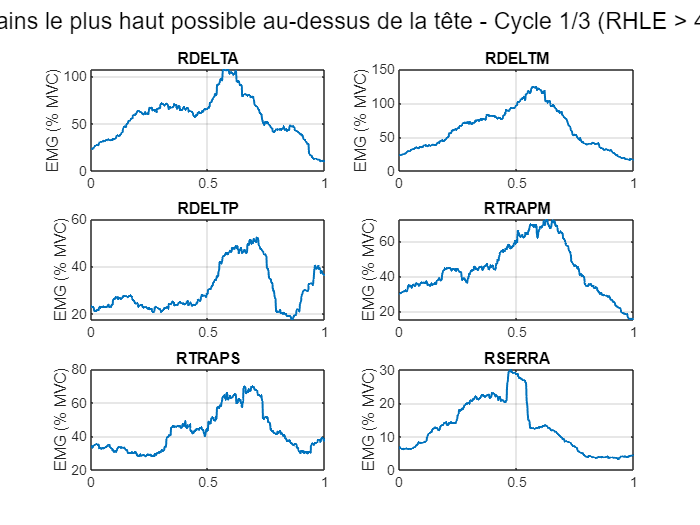

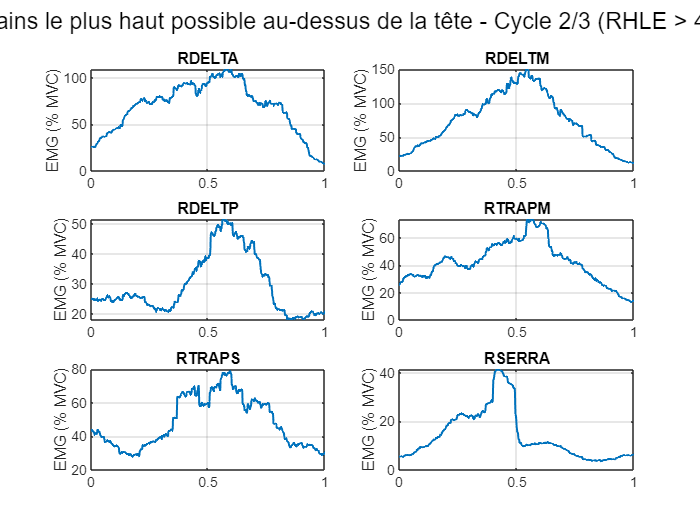

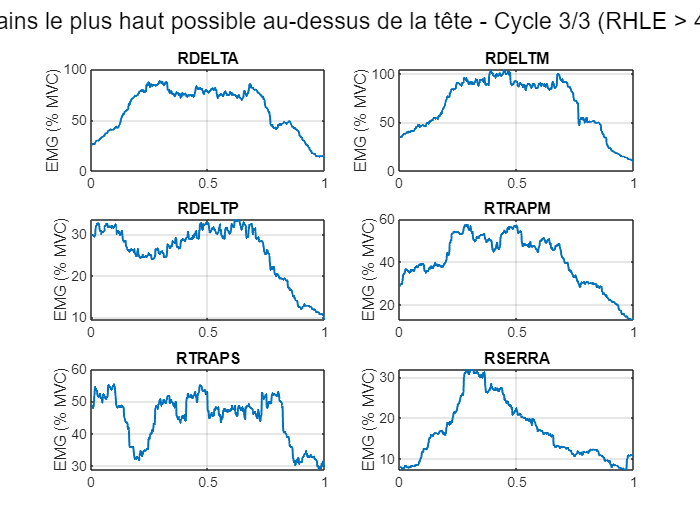

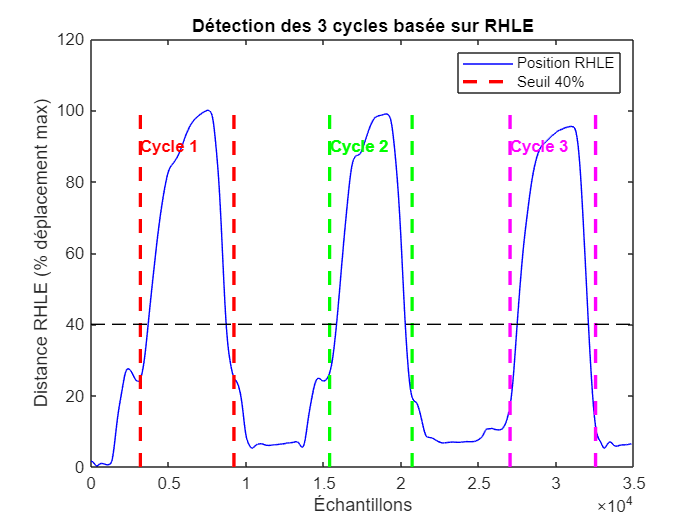

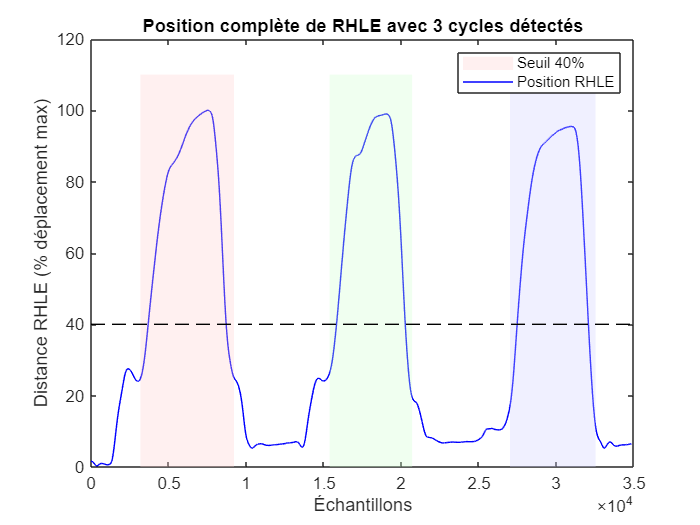


% Initialisation des paramètres avec le bon groupe
params = initializeParameters(groupe_choix);
nb_subjects = length(subjects);

% Calcul du MVC basé sur la tâche analytique assignée
mvc = calculateMVC(subjects, params);

% Sélection d'une tâche fonctionnelle unique
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Initialisation des données fonctionnelles
all_functional_data = cell(nb_subjects, params.nb_functional, params.nb_muscles, params.num_cycles);

% Traitement des données
for subj_idx = 1:nb_subjects
    all_functional_data = processFunctionalData(subjects{subj_idx}, selected_functional, mvc, params, all_functional_data, subj_idx);
end

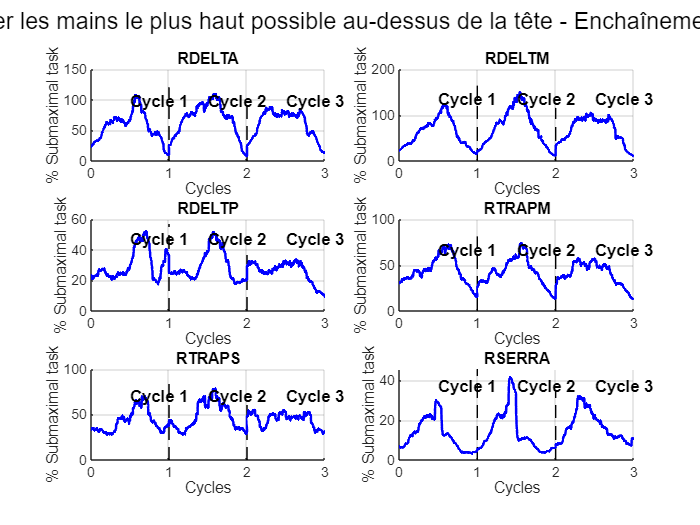


% Afficher l'enchaînement des cycles
plotCycleSequence(subjects, selected_functional, all_functional_data, params);


% Création et sauvegarde de la matrice de données
saveDataMatrix(subjects{1}, selected_functional, all_functional_data, params);

Matrice de données créée avec 6 muscles et 3000 points temporels
    RDELTA    RDELTM    RDELTP    RTRAPM    RTRAPS    RSERRA
    ______    ______    ______    ______    ______    ______

    23.233    22.483    23.275    29.598     33.85    6.2274
    23.408    22.844    22.947    30.101    33.871    6.3806
    23.571    23.054    23.051     30.11    33.791    6.4879
    23.592    23.169    23.088    30.069    34.052    6.6688
    23.528    23.258    23.063    30.243    33.916    6.8037
    23.418    23.285    23.059    30.299     33.38    6.6735
    23.456    23.168    22.891    30.437    33.388    6.4936
    23.408    23.024    22.832    30.291    33.251    6.4992
    23.707    23.088    22.882    30.225    33.727    6.4656
    24.325    23.127    22.904    30.839     34.56    6.408